## tmp_ADParameters

on_GPU = false;
T = 100; % sec
N = 200; % number of neurons 200
input_Hz = 50; % Hz
conn_prob_input2E = 0.1; % a.u.
conn_strength_input2E = 1; % a.u.
conn_prob_E2E = 0.25; % a.u.
conn_strength_E2E = 1; % a.u.
STDP_learning_rate_E2E = 1; % a.u. (STDP)

plasticity_type = "rbSTDP";

plot_synapses = false;
plot_Vm = false;
plot_spikes = false;
plot_refractoriness = false;
plot_weights = true;
plot_Hz = true;
plot_stimulation = false;
plot_STDP_traces = false;
plot_resource_pool = true;
plot_digraph = false;
plot_non_potentiable = false;
plot_dependence = false;

AD = true;
plot_AD = true;

## Run a single EI pool with

samples = 1;
pool_single = cell(samples);

parfor n=1:samples
    % Set up
    tic
    pool_single{n} = RB_STDP_EI_pool( ...
        T, ...
        N, ...
        on_GPU, ...
        conn_prob_input2E, ...
        conn_strength_input2E, ...
        conn_prob_E2E, ...
        conn_strength_E2E, ...
        plasticity_type, ...
        plot_synapses, ...
        plot_Vm, ...
        plot_spikes, ...
        plot_refractoriness, ...
        plot_weights, ...
        plot_Hz, ...
        plot_stimulation, ...
        plot_STDP_traces, ...
        plot_resource_pool, ...
        plot_digraph, ...
        plot_non_potentiable, ...
        plot_dependence, ...
        AD, ...
        plot_AD ...
        );
    pool_single{n}.set_input( ...
        input_Hz ...
        );
    toc
    % Run
    tStart = tic;
    pool_single{n}.run( ...
        false, ... % plot_during
        STDP_learning_rate_E2E ...
        );
    tEnd = toc(tStart);
    fprintf( ...
        'Elapsed time is %d minutes and %f seconds\n', ...
        floor(tEnd/60), ...
        rem(tEnd,60) ...
        );
    % Finish
    tic
    pool_single{n}.finish()
    toc
end

Elapsed time is 0.447461 seconds.


Elapsed time is 0.552032 seconds.
Elapsed time is 45 minutes and 38.198945 seconds
Elapsed time is 0.024445 seconds.


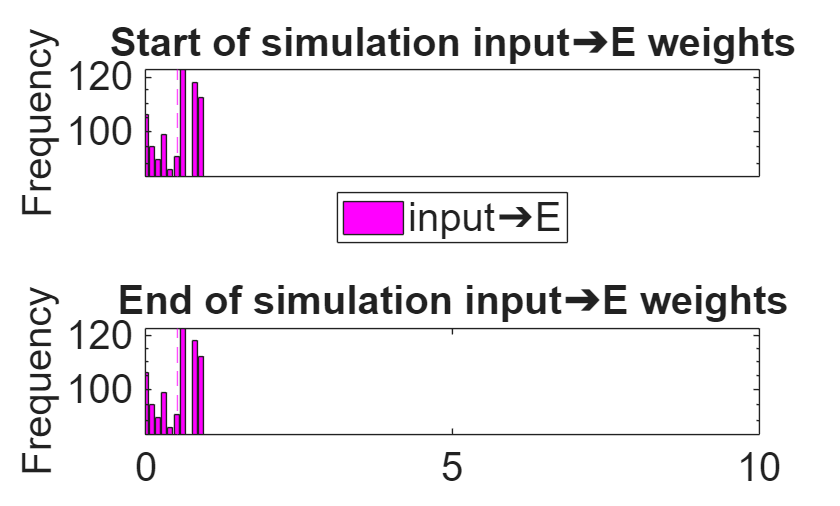

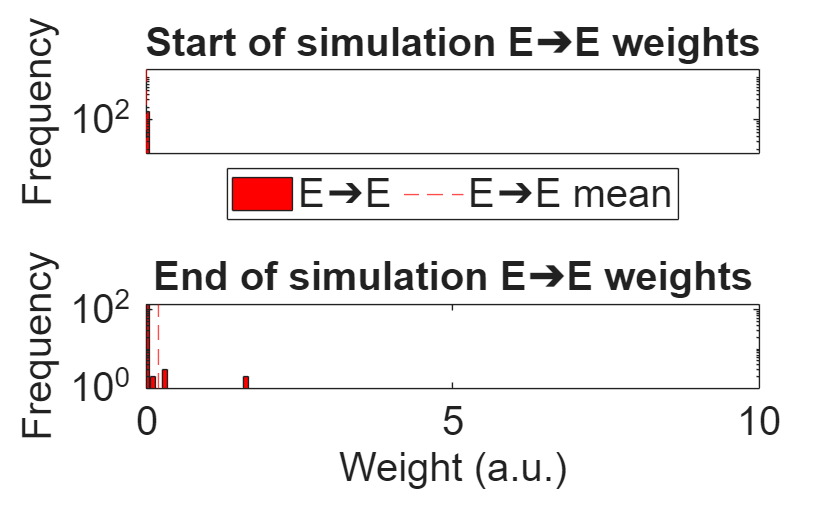

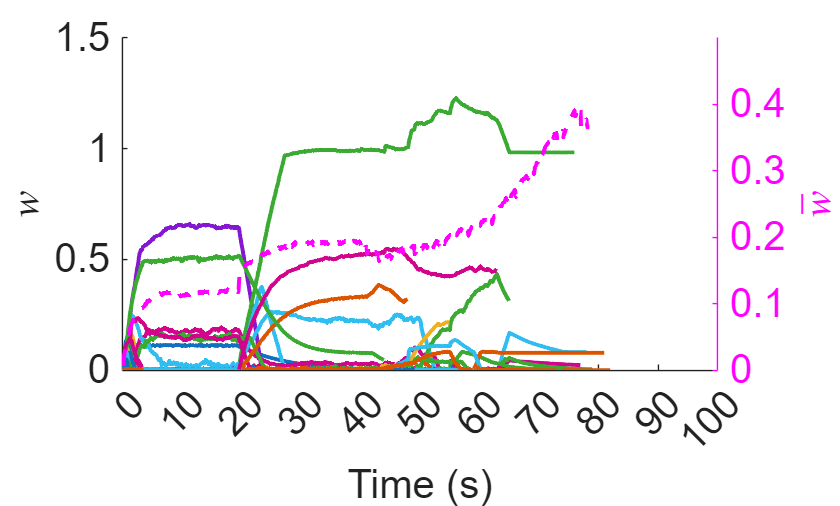

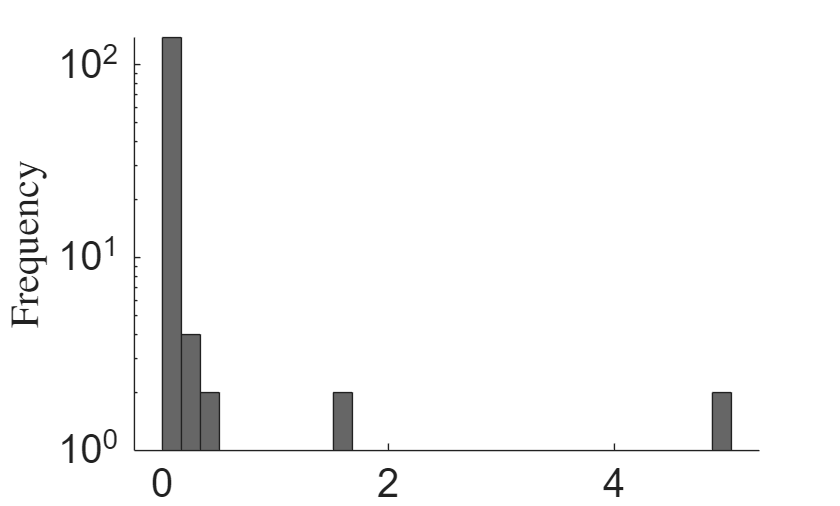

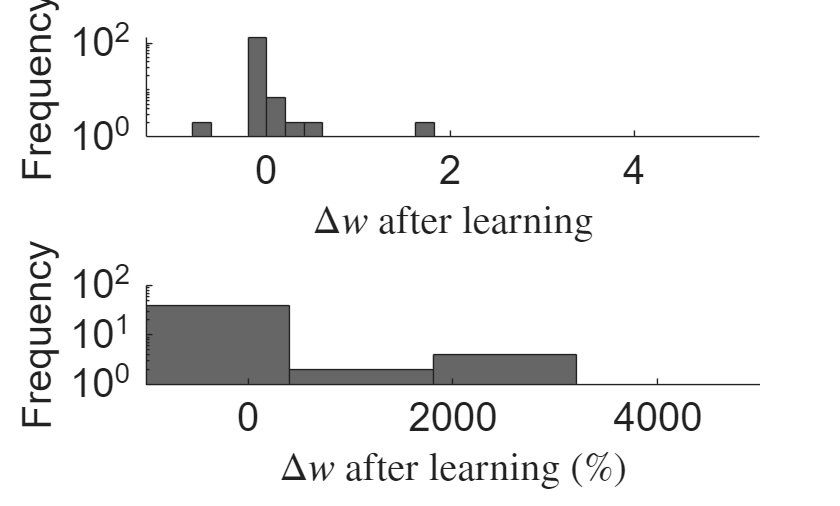

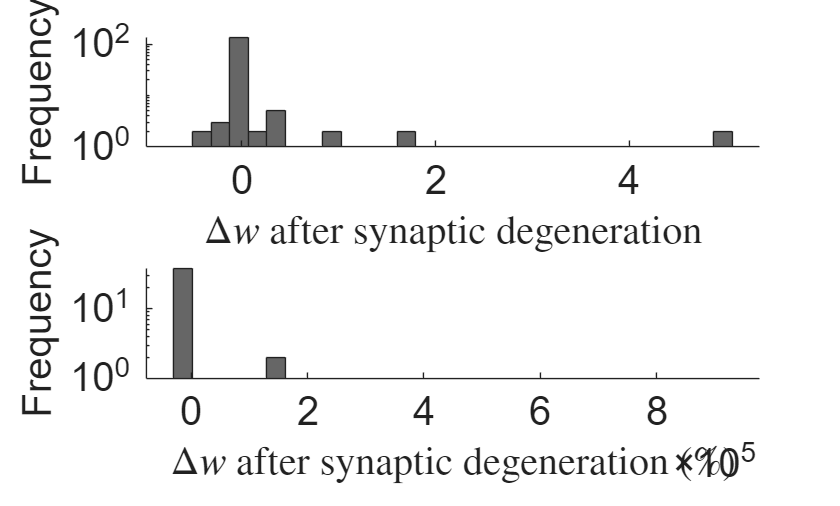

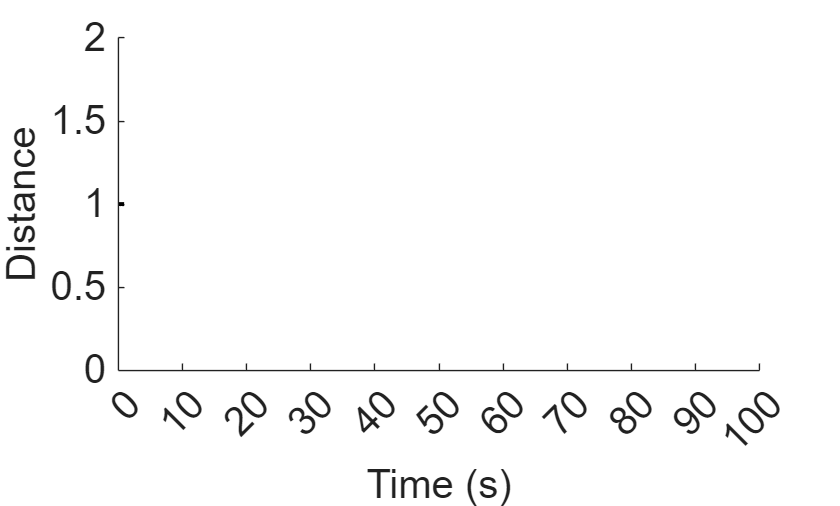

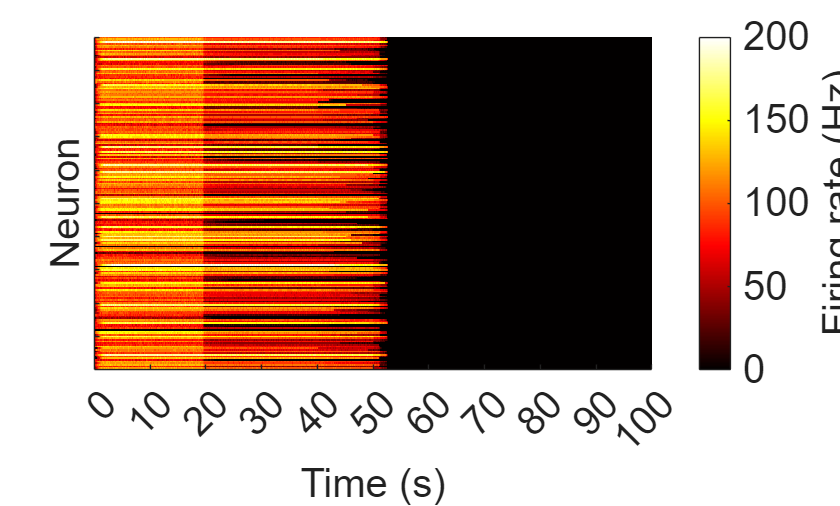

% Plot
tic
pool_single{1}.fontsize = 20;
pool_single{1}.plot( ...
    true ... % export
    )

toc

Elapsed time is 19.040381 seconds.


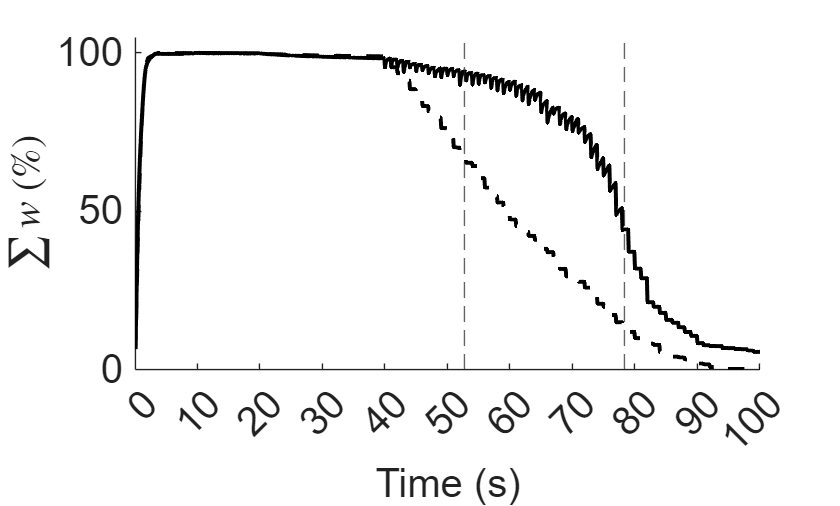

load current_rbSTDP_AD.mat
tmp_weights_AD = pool_single{1}.conn_weights_E2E_t;
load current_rbSTDP_AD_no_resources.mat
tmp_weights_AD_no_resources = pool_single{1}.conn_weights_E2E_t;

fig = figure();

tmp_weights = reshape( ...
    tmp_weights_AD, ...
    pool_single{1}.N * pool_single{1}.N, ...
    size(tmp_weights_AD, 3) ...
    );
tmp_weights(~any(tmp_weights,2), : ) = [];
tmp_sum_weights = zeros(size(tmp_weights, 2), 1);
for t = 1:size(tmp_weights, 2)
    tmp_sum_weights(t) = sum(nonzeros(tmp_weights(:, t)));
end
plot((tmp_sum_weights / max(tmp_sum_weights)) * 100, "black", "LineWidth", 2)

hold on
tmp_weights = reshape( ...
    tmp_weights_AD_no_resources, ...
    pool_single{1}.N * pool_single{1}.N, ...
    size(tmp_weights_AD_no_resources, 3) ...
    );
tmp_weights(~any(tmp_weights,2), : ) = [];
tmp_sum_weights = zeros(size(tmp_weights, 2), 1);
for t = 1:size(tmp_weights, 2)
    tmp_sum_weights(t) = sum(nonzeros(tmp_weights(:, t)));
end
plot((tmp_sum_weights / max(tmp_sum_weights)) * 100, "black", "LineStyle", "--", "LineWidth", 2)
hold off

box off
xlabel("Time (s)")
xticks(0:10.0 / pool_single{1}.save_resource_pools_t_period:pool_single{1}.T / pool_single{1}.save_resource_pools_t_period)
xticklabels(0:10:pool_single{1}.T)
ylabel("$\sum{w}$ (\%)", "Interpreter", "latex")
ylim([0 105])

xline(528, "--")
xline(784, "--")

fontsize(fig, pool_single{1}.fontsize, "points")
drawnow
exportgraphics(gcf,'figures/weights_E2E_sum.pdf','ContentType','vector')

load current_rbSTDP_AD.mat
tmp_Hz_AD = pool_single{1}.Hz_t;
load current_rbSTDP_AD_no_resources.mat
tmp_Hz_AD_no_resources = pool_single{1}.Hz_t;

fig = figure();

tmp_Hz_AD_sum = sum(tmp_Hz_AD > 0, 2);
plot((tmp_Hz_AD_sum / max(tmp_Hz_AD_sum)) * 100, "black", "LineWidth", 2)
find(tmp_Hz_AD_sum == 0, 1)

ans = 784

tmp_Hz_AD_sum(find(tmp_Hz_AD_sum == 0, 1) - 1)

ans = 16

hold on
tmp_Hz_AD_no_resources_sum = sum(tmp_Hz_AD_no_resources > 0, 2);
plot((tmp_Hz_AD_no_resources_sum / max(tmp_Hz_AD_no_resources_sum)) * 100, "black", "LineStyle", "--", "LineWidth", 2)
hold off
find(tmp_Hz_AD_no_resources_sum == 0, 1)

ans = 528

tmp_Hz_AD_no_resources_sum(find(tmp_Hz_AD_no_resources_sum == 0, 1) - 1)

ans = 9


box off
xlabel("Time (s)")
xticks(0:10.0 / pool_single{1}.save_Hz_t_period:pool_single{1}.T / pool_single{1}.save_Hz_t_period)
xticklabels(0:10:pool_single{1}.T)
ylabel("Num neurons active (%)")
ylim([0 105])

xline(528, "--")
xline(784, "--")


fontsize(fig, pool_single{1}.fontsize, "points")
drawnow
exportgraphics(gcf,'figures/Hz_sum.pdf','ContentType','vector')